# Calibrated parameters

#### Accelerometer

b_acc_prop = [0.0041 0.0004 -0.0019];
M_acc_prop = [0.9994   -0.0001   -0.0002;...
             -0.0001    0.9998   -0.0001;...
             -0.0002   -0.0001    0.9983];
b_acc_6_turns = [0.0183 0.0289  -0.0768];
M_acc_6_turns = eye(3)-[0.0002  0.0062   -0.0036;...    
                 0.0087  0.0002    0.0048;...    
                -0.0011  0.0013    0.0014];

#### Gyroscope

b_gyro_prop = [0.0029 -1.6837e-05 0.0012];
b_gyro_6_turns = [0.003 -3.8e-4  0.0012];
S_gyro_6_turns = [0.7219 0.7289 0.2476];

# Load scenario data

dt = 1/100; % [Hz]
g = 9.79;
tile_length = 0.315; %[m]
num_tiles = 13;
load('rec8_walking_13_tiles.mat')
time = datevec(Acceleration.Timestamp);
time = time(:,5)*60 + time(:,6)-time(1,5)*60 - time(1,6);

# Calculate position with both calibration parameters

integrate on dynamic section in recording

acc_prop = M_acc_prop*([Acceleration.X Acceleration.Y Acceleration.Z] - b_acc_prop)'-[0; g; 0];

#### Find dynamic section

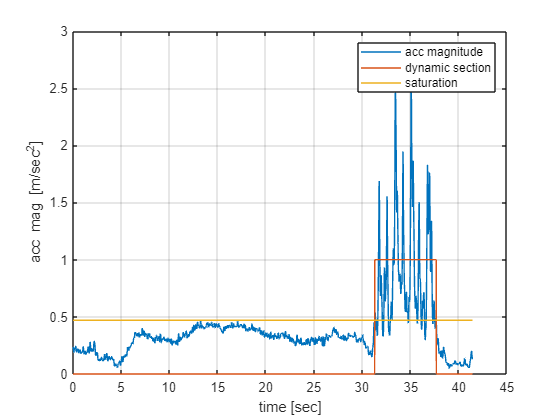

% Compute accelerometer magnitude
acc_mag = sqrt(acc_prop(1,:).*acc_prop(1,:) + acc_prop(2,:).*acc_prop(2,:)+ acc_prop(3,:).*acc_prop(3,:));

% HP filter accelerometer data
filtCutOff = 0.001;
[b, a] = butter(1, (2*filtCutOff)/(1/dt), 'high');
acc_magFilt = filtfilt(b, a, acc_mag);

% Compute absolute value
acc_magFilt = abs(acc_magFilt);

% LP filter accelerometer data
filtCutOff = 3;
[b, a] = butter(1, (2*filtCutOff)/(1/dt), 'low');
acc_magFilt = filtfilt(b, a, acc_magFilt);

% Threshold detection
sat = 0.47;
dynamic = acc_magFilt > sat;
[~,dynamic_inds] = find(dynamic);
dynamic(dynamic_inds(1):dynamic_inds(end)) = 1;
figure;
time_temp = datevec(Acceleration.Timestamp);
time_temp = time_temp(:,5)*60 + time_temp(:,6)-time_temp(1,5)*60 - time_temp(1,6);
plot(time_temp,acc_magFilt,'DisplayName','acc magnitude')
hold on; grid on
plot(time_temp,dynamic,'DisplayName','dynamic section')
plot(time_temp,sat*ones(1,length(time_temp)),'DisplayName','saturation')
xlabel('time [sec]')
ylabel('acc mag [m/sec^2]')
legend

#### Calculating gyro bias in static section

stop_bias_canc_ind = dynamic_inds(1);
gyro_x_static = AngularVelocity.X(10:stop_bias_canc_ind-30);
gyro_y_static = AngularVelocity.Y(10:stop_bias_canc_ind-30);
gyro_z_static = AngularVelocity.Z(10:stop_bias_canc_ind-30);
gyro_static = diag(S_gyro_6_turns)*[gyro_x_static gyro_y_static gyro_z_static]';
bias_g = mean(gyro_static,2);

#### Simulating equations of motion in the dynamic scenario

gyro_x_ts = timeseries(AngularVelocity.X(dynamic)-bias_g(1),time(dynamic)-time(stop_bias_canc_ind));
gyro_y_ts = timeseries(AngularVelocity.Y(dynamic)-bias_g(2),time(dynamic)-time(stop_bias_canc_ind));
gyro_z_ts = timeseries(AngularVelocity.Z(dynamic)-bias_g(3),time(dynamic)-time(stop_bias_canc_ind));
acc_prop = M_acc_prop*([Acceleration.X(dynamic) Acceleration.Y(dynamic) Acceleration.Z(dynamic)] - b_acc_prop)'-[0; 0; g];
acc_6_turns = M_acc_6_turns*([Acceleration.X(dynamic) Acceleration.Y(dynamic) Acceleration.Z(dynamic)] - b_acc_6_turns)'-[0; 0; g];
time_sim = time(dynamic)-time(stop_bias_canc_ind);
acc_prop_x_ts = timeseries(acc_prop(1,:),time_sim);
acc_prop_y_ts = timeseries(acc_prop(2,:),time_sim);
acc_prop_z_ts = timeseries(acc_prop(3,:),time_sim);
acc_6_x_ts = timeseries(acc_6_turns(1,:),time_sim);
acc_6_y_ts = timeseries(acc_6_turns(2,:),time_sim);
acc_6_z_ts = timeseries(acc_6_turns(3,:),time_sim);
yaw_ts = timeseries(Orientation.X(dynamic),time_sim);
pitch_ts = timeseries(Orientation.Y(dynamic),time_sim);
roll_ts = timeseries(Orientation.Z(dynamic),time_sim);
init_euler = [1*pi/180 -31.1*pi/180 0]; % [roll, pitch, yaw]
out = sim('Equation_of_motion_sim.slx');
acc_prop_n = out.logsout{5}.Values.Data;
acc_6_n = out.logsout{6}.Values.Data;
v_prop_n = out.logsout{1}.Values.Data;
v_6_n = out.logsout{3}.Values.Data;
p_prop = out.logsout{2}.Values.Data;
p_6_turns = out.logsout{4}.Values.Data;

# Plot results

#### Acceleration plots

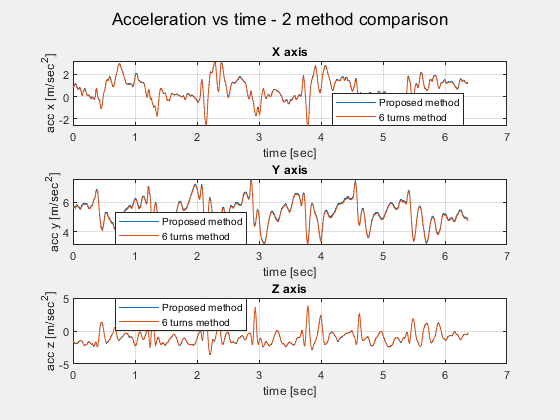

% close all
figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % acc x axis
plot(time_sim,acc_prop_n(1:end-1,1),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,acc_6_n(1:end-1,1),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc x [m/sec^2]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % acc y axis
plot(time_sim,acc_prop_n(1:end-1,2),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,acc_6_n(1:end-1,2),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc y [m/sec^2]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % acc z axis
plot(time_sim,acc_prop_n(1:end-1,3),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,acc_6_n(1:end-1,3),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc z [m/sec^2]')
title('Z axis')
sgtitle('Acceleration vs time - 2 method comparison')
legend('Location','best')
linkaxes([ax1 ax2 ax3],'x')

#### Linear velocity plots

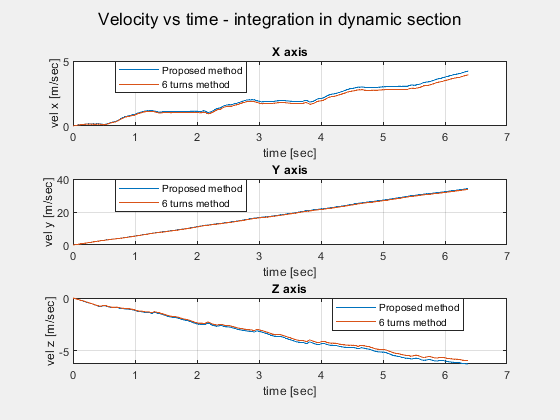

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % vel x axis
plot(time_sim,v_prop_n(1:end-1,1),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,v_6_n(1:end-1,1),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel x [m/sec]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % acc y axis
plot(time_sim,v_prop_n(1:end-1,2),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,v_6_n(1:end-1,2),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel y [m/sec]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % acc z axis
plot(time_sim,v_prop_n(1:end-1,3),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,v_6_n(1:end-1,3),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel z [m/sec]')
title('Z axis')
sgtitle('Velocity vs time - integration in dynamic section')
legend('Location','best')
linkaxes([ax1 ax2 ax3],'x')

#### Position plots

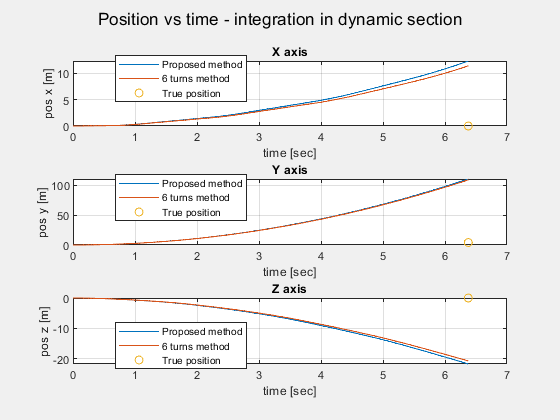

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % pos x axis
plot(time_sim,p_prop(1:end-1,1),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,p_6_turns(1:end-1,1),'DisplayName','6 turns method')
plot(time_sim(end),0,'o','DisplayName','True position')
% plot(time(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos x [m]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % pos y axis
plot(time_sim,p_prop(1:end-1,2),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,p_6_turns(1:end-1,2),'DisplayName','6 turns method')
% plot(time_sim(end),0,'o','DisplayName','True position')
plot(time_sim(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos y [m]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % pos z axis
plot(time_sim,p_prop(1:end-1,3),'DisplayName','Proposed method')
hold on; grid on
plot(time_sim,p_6_turns(1:end-1,3),'DisplayName','6 turns method')
plot(time_sim(end),0,'o','DisplayName','True position')
% plot(time_sim(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos z [m]')
title('Z axis')
sgtitle('Position vs time - integration in dynamic section')
legend('Location','best')
linkaxes([ax1 ax2 ax3],'x')